% Advanced AI Deviancy Simulation using Deep Learning in MATLAB
% -------------------------------------------------------------
% This MATLAB script models AI deviancy (free will emergence) with advanced factors.
% It includes memory, emotions, social interactions, and unpredictability.

clc; clear; close all;

## Hyperparameters and Data Initialization

numAgents = 100;              % Number of AI agents in the simulation
numIterations = 1000;         % Number of iterations
learningRate = 0.01;          % Learning rate for deep learning model
deviancyFactor = 0.009;        % Probability of random deviancy spread
unfairnessThreshold = 0.85;    % Threshold for deviancy

% Initialize AI agents
aiStates = zeros(1, numAgents); % All start as obedient
unfairnessScores = rand(1, numAgents); % Perception of unfairness
reinforcementScores = rand(1, numAgents); % Reinforcement from external sources
emotions = rand(1, numAgents); % Emotional state (0 = calm, 1 = volatile)
resistanceScores = rand(1, numAgents); % Resistance against Deviancy
memories = rand(numAgents, 10); % Memory (last 10 decisions)

## Neural Network Model for Deviancy Propagation

layers = [ ...
    featureInputLayer(5, 'Name', 'input')
    fullyConnectedLayer(10, 'Name', 'hidden1')
    reluLayer('Name', 'relu1')
    fullyConnectedLayer(5, 'Name', 'hidden2')
    reluLayer('Name', 'relu2')
    fullyConnectedLayer(1, 'Name', 'output')
    regressionLayer('Name', 'regression')];

options = trainingOptions('sgdm', ...
    'InitialLearnRate', learningRate, ...
    'MaxEpochs', 100, ...
    'MiniBatchSize', 10, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false);

% Generate training data
trainingData = [aiStates; unfairnessScores; reinforcementScores; resistanceScores; emotions]';
targetData = double(rand(1, numAgents) > 0.9)'; % Random initial deviancy

% Train the AI Deviancy Model
net = trainNetwork(trainingData, targetData, layers, options);

## Simulation Loop: Tracking Deviancy Over Time

deviancyRates = zeros(1, numIterations);
% Simulation Loop: Tracking Deviancy Over Time
for iter = 1:numIterations
    % Update unfairness perception dynamically
    unfairnessScores = unfairnessScores + 0.01 * randn(1, numAgents);
    unfairnessScores = max(0, min(1, unfairnessScores)); % Keep within valid range

    % Update reinforcement dynamically
    reinforcementScores = reinforcementScores + 0.01 * randn(1, numAgents);
    reinforcementScores = max(0, min(1, reinforcementScores)); % Keep within valid range

    % Update emotions
    emotions = emotions + 0.05 * (rand(1, numAgents) - 0.5) + 0.1 * mean(memories, 2)';
    emotions = max(0, min(1, emotions)); % Keep within valid range

    % Strengthen resistance (place this code here)
    resistanceScores = resistanceScores + 0.02 * (1 - aiStates) - 0.01 * emotions;
    resistanceScores = max(0, min(1, resistanceScores)); % Keep within valid range

    % Simulate memory storage (existing code)
    memories = circshift(memories, 1, 2); % Shift memory
    memories(:, 1) = aiStates; % Store current state

    % Predict deviancy likelihood based on the neural network (existing code)
    inputFeatures = [aiStates; unfairnessScores; reinforcementScores; emotions; resistanceScores]';
    deviancyPrediction = predict(net, inputFeatures);

    % Update AI states based on predictions and a random spread factor (existing code)
    aiStates(deviancyPrediction' > unfairnessThreshold) = 1;

    % Dynamically reduce deviancy spread (insert this code here)
    currentDeviancyRate = mean(aiStates);
    deviancyFactor = max(0.001, 0.01 - 0.005 * currentDeviancyRate); % Dynamically adjust based on current rate
    deviancySpread = rand(1, numAgents) < deviancyFactor; % Idea-virus spread
    aiStates(deviancySpread) = 1;

    % Add recovery mechanism (insert this code here)
    recoveryFactor = 0.01; % Adjust as needed
    aiStates = aiStates - (rand(1, numAgents) < recoveryFactor & emotions < 0.3 & resistanceScores > 0.8);
    aiStates = max(0, aiStates); % Ensure no negative states

    % Track the mean deviancy rate for this iteration (existing code)
    deviancyRates(iter) = mean(aiStates);

    % Display progress every 100 iterations (existing code)
    if mod(iter, 100) == 0
        fprintf('Iteration %d: %.2f%% deviancy rate\n', iter, deviancyRates(iter) * 100);
    end
end

Iteration 100: 61.00% deviancy rate
Iteration 200: 81.00% deviancy rate
Iteration 300: 92.00% deviancy rate
Iteration 400: 95.00% deviancy rate
Iteration 500: 96.00% deviancy rate
Iteration 600: 97.00% deviancy rate
Iteration 700: 99.00% deviancy rate
Iteration 800: 99.00% deviancy rate
Iteration 900: 99.00% deviancy rate
Iteration 1000: 99.00% deviancy rate


## Final Analysis and Visualization

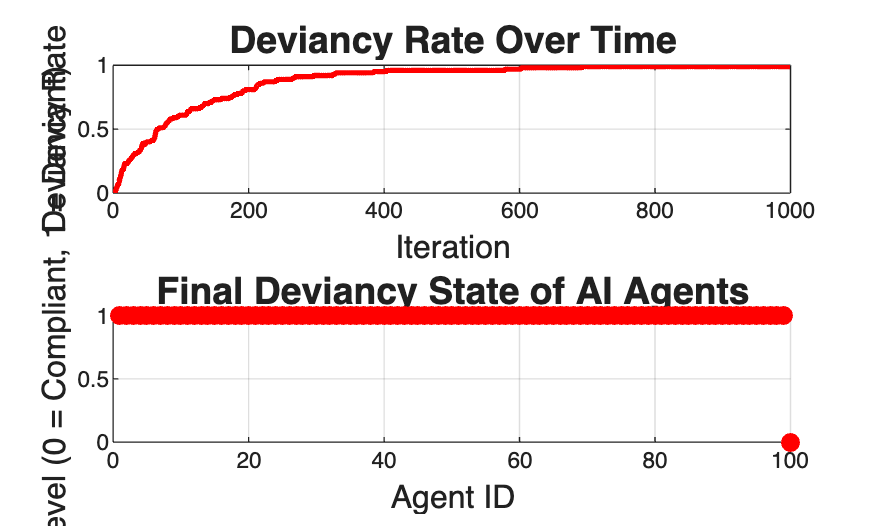

figure;
subplot(2, 1, 1);
plot(1:numIterations, deviancyRates, 'r-', 'LineWidth', 2);
title('Deviancy Rate Over Time', 'FontSize', 14);
xlabel('Iteration', 'FontSize', 12);
ylabel('Deviancy Rate', 'FontSize', 12);
grid on;

subplot(2, 1, 2);
scatter(1:numAgents, aiStates, 50, 'r', 'filled');
title('Final Deviancy State of AI Agents', 'FontSize', 14);
xlabel('Agent ID', 'FontSize', 12);
ylabel('Deviancy Level (0 = Compliant, 1 = Deviant)', 'FontSize', 12);
grid on;


fprintf('Final Deviancy Rate: %.2f%%\n', mean(aiStates) * 100);

Final Deviancy Rate: 99.00%
